# Algoritmos Numéricos por Computadora

# Primer parcial - Primavera 2020

Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).

Sube tu archivo resultado a comunidad $\to$ primerParcial antes de las 10am.

## Formato IEEE 754. Punto flotante de doble precisión.

1. [2 puntos] 

a) Explica a detalle la representación hexadecimal del número 2.125  en el  formato IEEE 754: $x=\textrm{signo}\;\left(1+f\right)2^e$. En el siguiente código inserta tus observaciones y cálculos para determinar: *signo*, *e*, *f *y *x*. 

% Escribe aquí tus observaciones y cálculos
xri = num2hex(2.125)

xri = '4001000000000000'

%El numero en hexa es 4001000000000000
% En este caso 4 -> 0100 y el bit mas significativo= 0.
%Si el primer bit es 0 => el numero es positivo (1)
%Si el primer bit es 1 => el numero es negativo (-1)
signo=1;

%Los primeros 3 caracteres sin contar el bit del signo 
beV= [4 0 0];
aux = [2 1 0];
be=sum(beV.*16.^aux);
e= be-1023;

fVec = [1 0 0 0 0 0 0 0 0 0 0 0 0]; 
i = 1:13; %Index de sus respectivas posiciones
f = sum(fVec./(16.^i)); %Hago la suma de tal modo que sea un agregado del valor en decimal de cada dígito hexadecimal
x1 = signo*(1 + f) * 2^e;
disp(x1); %aqui se ve que el resultado nos da 2.1250 

    2.1250



b) Repite ejercicio anterior pero ahora con el número -1.1

x2 = num2hex(-1.1)

x2 = 'bff199999999999a'

%El numero en hexa es bff199999999999a
% En este caso b -> 1011 y el bit mas significativo= 0.
%Si el primer bit es 0 => el numero es positivo (1)
%Si el primer bit es 1 => el numero es negativo (-1)
signo=-1;

%Los primeros 3 caracteres sin contar el bit del signo (11-8)=3 => 3ff
beV= [3 15 15];
aux = [2 1 0];
be=sum(beV.*16.^aux);
e= be-1023;

fVec = [1 9 9 9 9 9 9 9 9 9 9 9 10]; 
i = 1:13; %Index de sus respectivas posiciones
f = sum(fVec./(16.^i)); %Hago la suma de tal modo que sea un agregado del valor en decimal de cada dígito hexadecimal
x2 = signo*(1 + f) * 2^e;
disp(x2); %aqui se ve que el resultado nos da -1.100.

   -1.1000



## Raíces de funciones

2. [2 puntos] Considera un tanque esférico de radio R. El volumen del líquido contenido en el tanque es función de la altura h:


$$V=\pi h^2 \left(\frac{3R-h}{3}\right)$$


Calcula a qué altura hay que llenar un tanque de radio R=3 *m* para tener un volumen V= 30 $m^3$. 

Utiliza el método de la secante (escribe el código más abajo) o utiliza la función fzero de Matlab.

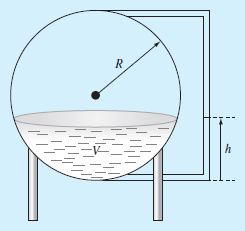

% El código no debe generar warnings


3. [2 puntos] Determina todas las raíces de $f\left(x\right)=-14-20x+19x^2 -3x^3$. Grafica el polinomio para identificar en qué regiones se encuentran las raíces.

% El código no debe generar warnings
f= @(x) -14 -20*x +19*x.^2-3*x.^3

f = function_handle with value:
    @(x)-14-20*x+19*x.^2-3*x.^3


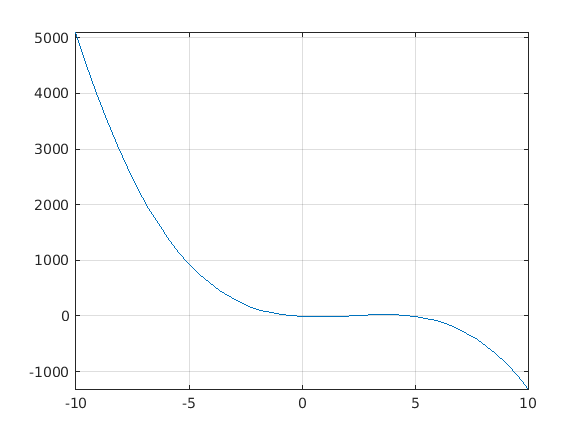

a=-10;
b=10;
fplot(f,[a,b])
grid on

[x,i]=

## Optimización

4. [2 puntos] Encuentra el máximo de la función


$$f\left(x\right)=2\sin \left(x\right)-\frac{x^2 }{10}$$


en el intervalo [0,5].

Utiliza el método de Newton (escribe el código más abajo) o utiliza la función fminbnd de Matlab.

% El código no debe generar warnings


5. [1 punto] Método de la secante.

function [x,i] = secante(f, a, b)
    MAX=100;
    rtol=eps;
    i=0;
    
    do=true;
    
    while do
        fx1=f(a);
        fx2=f(b);
        
        sn=(fx1-fx2)/(a-b);
        b=a;
        a=a-(fx1/sn);

        i=i+1;
        do= i<MAX && abs(a-b)>abs(a)*rtol && fx1~=0;
    end
    x=a;
end

6. [1 punto] Método de Newton para encontrar puntos críticos. 

Observa que la función debe regresar tres resultados. La variable min indíca si el punto crítico es un mínimo o un máximo.

function [x,i, min] = NewtonOptimizacion(f,x)
% Supone funciones doblemente diferenciables
% Encuentra un punto crítico de f
% min - indica si se trata de un mínimo (true) o máximo (false)


end

Newton Raphson para encontrar raices

function [x,i] = newtonRaphson(f, a, b)
    fsym= sym(f);
    dfs= diff(fsym);
    df= matlabFunction(dfs);
    if nargin(df) == 0
        cte=df();
        df= @(x) cte + 0*x;
    end
    
    MAX=100;
    rtol=eps;
    
    x=(a+b)/2;
    i=0;
    
    do=true;
    while do
        xp=x;
        x=xp-f(xp)/df(xp);
        fx=f(x);
        i=i+1;
        do=(abs(x-xp)/abs(x)>rtol && fx~=0 && i<MAX);
    end
end
